# **PESTools - Example 003 - Showcase of the available ARPES model curves that can be used for fitting**

This example shows all of the curve line-shapes that are available to use when fitting to either ARPES or XPS data obtained from the ADRESS beamline. 

- **For ARPES curves:** **2D** **Gaussian**, **2D** **Lorentzian**, **2D** **Voigt** functions are available.

- The **Fermi-Dirac Distribution** **(FDD)** is also used if necessary for fitting states near the Fermi-edge.

- Using the 2D model curves, band dispersions can be plotted and compared to data.

close all; clear all;
pp = plot_props();

# **Symmetric Spot Profiles**

xdat = linspace(-3, 3, 1e2);
ydat = linspace(-3, 3, 1e2);

## (1) Gaussian 2D Spot Profile

help G2D;

  int = G2D(xdat, ydat, peak, x0, y0, fwhm)
    Function that evaluates a 2D Gaussian curve after defining its amplitude
    and position in the x- and y-axis. The function assumes that the FWHM
    is identical both in the x- and y-dimensions.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       [1×M] row vector of the x-axis input domain (kx for ARPES)
    -   ydat:       [N×1] column vector of the y-axis input domain (Eb for ARPES)
    -   peak:       scalar of the maximum peak height of the Gaussian.
    -   x0:         scalar of the peak position along the x-axis of the Gaussian.
    -   y0:         scalar of the peak position along the y-axis of the Gaussian.
    -   fwhm:       scalar of the full-width at half-maximum (FWHM) of the Gaussian along both x- and y-axes.
 
    OUT:
    -   int:        [N×M] array of the output Gaussian spot profile



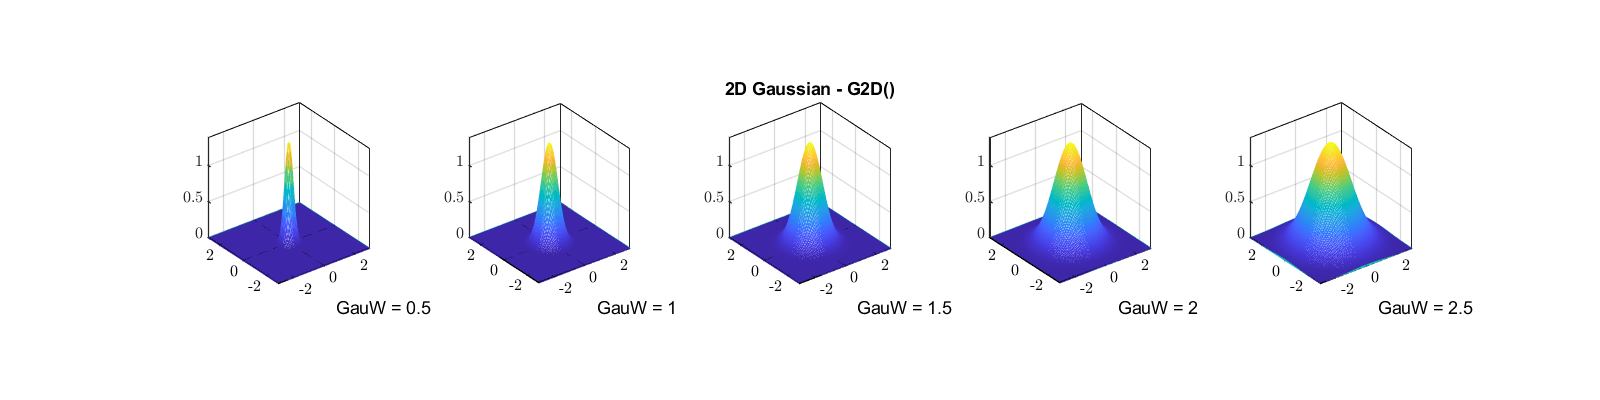

% 1 - Defining the input parameters
peak        = 1.38;         % scalar of the peak beneath the Gaussian.
x0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
y0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
fwhm       = 0.5:0.5:2.5;   % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
% 2 - Calculating the 2D lineshape
lgnd = {};
for i = 1:length(fwhm)
    int_gauss{i}    = G2D(xdat, ydat, peak, x0, y0, fwhm(i));
    lgnd{i}         = "GauW = " + string(fwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); 
fig.Position(3) = 4.*pp.fig4x4(1);
fig.Position(4) = 1.*pp.fig4x4(2);
for i = 1:length(fwhm)
    subplot(1,length(fwhm),i)
    meshz(xdat, ydat, int_gauss{i});
    gca_props(); axis square;
    xlabel(lgnd{i}); 
    if i == 3; title('2D Gaussian - G2D()'); end
end

## (2) Lorentzian 2D Spot Profile

help L2D;

  int = L2D(xdat, ydat, peak, x0, y0, fwhm)
    Function that evaluates a 2D Lorentzian curve after defining its amplitude
    and position in the x- and y-axis. The function assumes that the FWHM
    is identical both in the x- and y-dimensions.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       [1×M] row vector of the x-axis input domain (kx for ARPES)
    -   ydat:       [N×1] column vector of the y-axis input domain (Eb for ARPES)
    -   peak:       scalar of the maximum peak height of the Lorentzian.
    -   x0:         scalar of the peak position along the x-axis of the Lorentzian.
    -   y0:         scalar of the peak position along the y-axis of the Lorentzian.
    -   fwhm:       scalar of the full-width at half-maximum (FWHM) of the Lorentzian along both x- and y-axes.
 
    OUT:
    -   int:        [N×M] array of the output Lorentzian spot profile



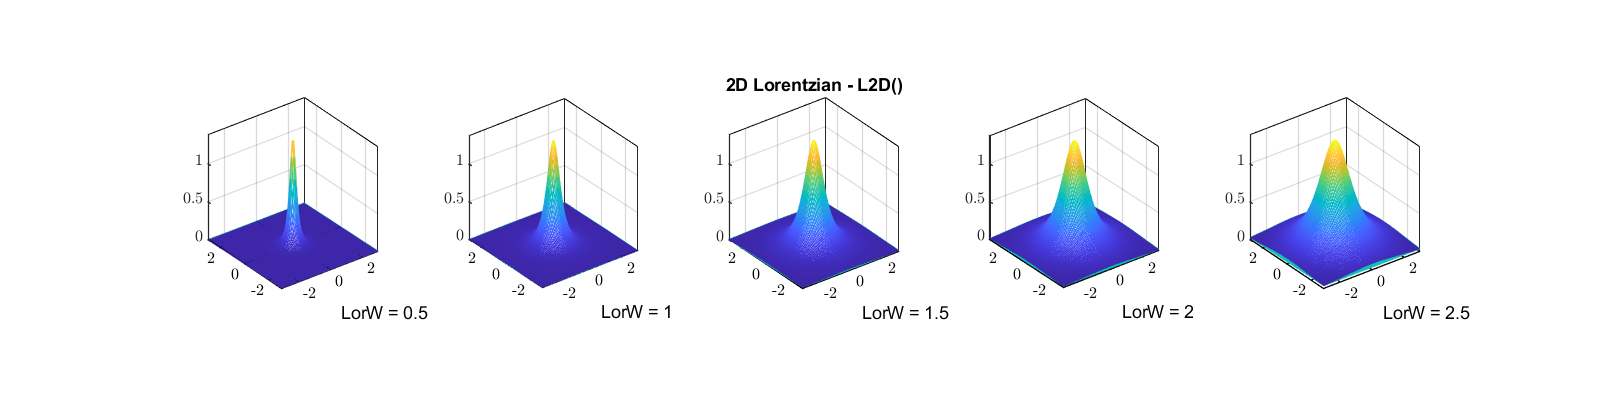

% 1 - Defining the input parameters
peak        = 1.38;         % scalar of the peak beneath the Gaussian.
x0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
y0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
fwhm       = 0.5:0.5:2.5;   % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
% 2 - Calculating the 2D lineshape
lgnd = {};
for i = 1:length(fwhm)
    int_lorz{i}    = L2D(xdat, ydat, peak, x0, y0, fwhm(i));
    lgnd{i}         = "LorW = " + string(fwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); 
fig.Position(3) = 4.*pp.fig4x4(1);
fig.Position(4) = 1.*pp.fig4x4(2);
for i = 1:length(fwhm)
    subplot(1,length(fwhm),i)
    meshz(xdat, ydat, int_lorz{i});
    gca_props(); axis square;
    xlabel(lgnd{i}); 
    if i == 3; title('2D Lorentzian - L2D()'); end
end

# **Asymmetric Spot Profiles**

xdat = linspace(-3, 3, 1e2);
ydat = linspace(-3, 3, 1e2);

## (1) Asymmetric Gaussian 2D Spot Profile

help G2DA;

  int = G2DA(xdat, ydat, peak, x0, y0, xfwhm, yfwhm)
    Function that evaluates a 2D Gaussian curve after defining its position,
    full-width at half-maximum (FWHM) and amplitude in both the x- and
    y-axis.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       [1×M] row vector of the x-axis input domain (kx for ARPES)
    -   ydat:       [N×1] column vector of the y-axis input domain (Eb for ARPES)
    -   peak:       scalar of the maximum peak height of the Gaussian.
    -   x0:         scalar of the peak position along the x-axis of the Gaussian.
    -   y0:         scalar of the peak position along the y-axis of the Gaussian.
    -   xfwhm:      scalar of the full-width at half-maximum (FWHM) of the Gaussian along the x-axis.
    -   yfwhm:      scalar of the full-width at half-maximum (FWHM) of the Gaussian along the y-axis.
 
    OUT:
    -   int:        [N×M] array of the output Asymetrical Gaussian spot profile



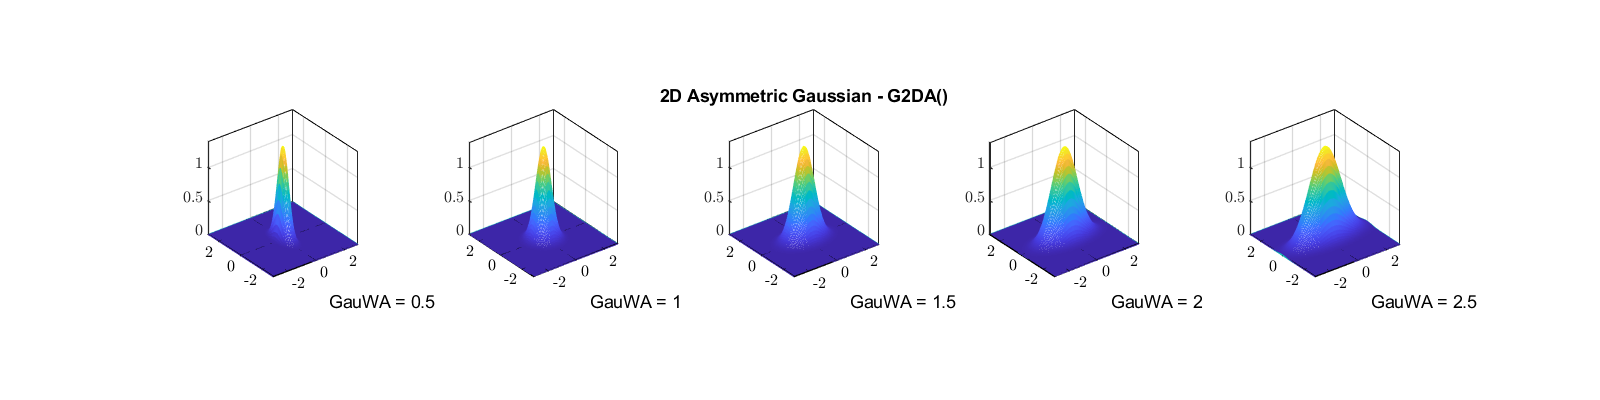

% 1 - Defining the input parameters
peak        = 1.38;         % scalar of the peak beneath the Gaussian.
x0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
y0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
xfwhm       = 0.5:0.5:2.5;  % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
yfwhm       = 1;            % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
% 2 - Calculating the 2D lineshape
lgnd = {};
for i = 1:length(xfwhm)
    int_gauss{i}    = G2DA(xdat, ydat, peak, x0, y0, xfwhm(i), yfwhm);
    lgnd{i}         = "GauWA = " + string(xfwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); 
fig.Position(3) = 4.*pp.fig4x4(1);
fig.Position(4) = 1.*pp.fig4x4(2);
for i = 1:length(xfwhm)
    subplot(1,length(xfwhm),i)
    meshz(xdat, ydat, int_gauss{i});
    gca_props(); axis square;
    xlabel(lgnd{i}); 
    if i == 3; title('2D Asymmetric Gaussian - G2DA()'); end
end

# **Angle-resolved band dispersions plotted using Gaussian spot profiles**

The function 'ARPESCurve()' can be used to call any 2D curve line-shape that is plotted with a particular effective mass and energy.

Using a linear combination of 'ARPESCurve()' outputs, we can then fit to any ARPES band dispersions.

## (1) Generic ARPES Curve

help ARPESCurve;

  zdat = ARPESCurve(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR, plot_result)
    Function that evaluates a generic angle-resolved photoelectron 
    spectroscopy (ARPES) curve in 2D. This can be used to model an ARPES
    spectrum, that is built up by a sum of individual Gaussians.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       [1×M] row vector of the x-axis input domain (kx for ARPES)
    -   ydat:       [N×1] column vector of the y-axis input domain (Eb for ARPES)
    -   cTYPE:      type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
    -   INT:    	scalar of the peak intensity of 2D PE curve.
    -   XLOC:      	scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion [Ang^-1].
    -   YLOC:      	scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion [eV].
    -   XFWHM:     	scalar of the x-axis FWHM for each Gaussian (k-resolution) [Ang^-1]
    -   YFWHM:     	scalar of the y-axis FWH

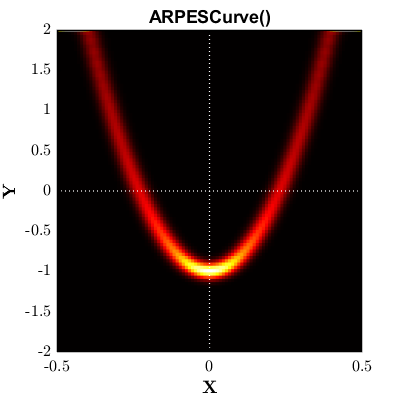

% 1 - Defining the input parameters
xdat = linspace(-0.5, 0.5, 1e2);    % 1xM row vector of the x-axis domain
ydat = linspace(-2, 2, 1e2)';        % Nx1 column vector of the y-axis domain
cTYPE   = "G2DA";       % type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
INT     = 1.0;          % scalar of the peak intensity of 2D PE curve.
XLOC    = 0.00;         % scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion.
YLOC    = -1.00;        % scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion.
XFWHM   = 0.05;         % scalar of the x-axis FWHM for each Gaussian (k-resolution)
YFWHM   = 0.15;         % scalar of the y-axis FWHM for each Gaussian (Eb-resolution)
MSTAR   = 0.20;         % scalar of the effective mass, which governs the curvature of the parabola.
% 2 - Calculating the lineshape
zdat    = ARPESCurve(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR, 1);

## (2) Generic ARPES Curve with FDD Convolution

help ARPESCurve_FDD;

  zdat = ARPESCurve_FDD(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR, FDEF, FDT, plot_result)
    Function that evaluates a generic angle-resolved photoelectron 
    spectroscopy (ARPES) curve in 2D. This can be used to model an ARPES
    spectrum, that is built up by a sum of individual Gaussians.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       [1×M] row vector of the x-axis input domain (kx for ARPES)
    -   ydat:       [N×1] column vector of the y-axis input domain (Eb for ARPES)
    -   cTYPE:      type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
    -   INT:    	scalar of the peak intensity of 2D PE curve.
    -   XLOC:      	scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion [Ang^-1].
    -   YLOC:      	scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion [eV].
    -   XFWHM:     	scalar of the x-axis FWHM for each Gaussian (k-resolution) [Ang^-1]
    -   YFWHM:     	scalar of

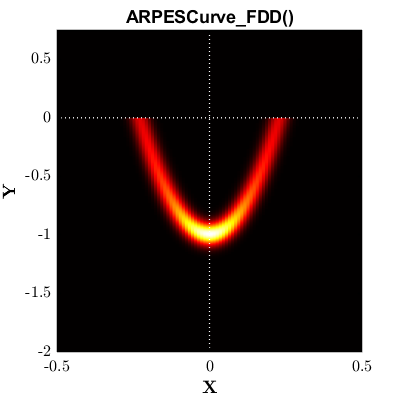

% 1 - Defining the input parameters
xdat = linspace(-0.5, 0.5, 1e2);    % 1xM row vector of the x-axis domain
ydat = linspace(-2, 0.75, 1e3)';        % Nx1 column vector of the y-axis domain
cTYPE   = "G2DA";       % type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
INT     = 1.0;          % scalar of the peak intensity of 2D PE curve.
XLOC    = 0.00;         % scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion.
YLOC    = -1.00;        % scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion.
XFWHM   = 0.05;         % scalar of the x-axis FWHM for each Gaussian (k-resolution)
YFWHM   = 0.15;         % scalar of the y-axis FWHM for each Gaussian (Eb-resolution)
MSTAR   = 0.20;         % scalar of the effective mass, which governs the curvature of the parabola.
FDEF    = 0.00;         % scalar of the FDD Fermi-Level position.
FDT     = 12.0;         % scalar of the FDD temperature.
% 2 - Calculating the lineshape
zdat    = ARPESCurve_FDD(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR, FDEF, FDT, 1);

## (3) Generic ARPES Curve with FDD Convolution + Gaussian broadening

help ARPESCurve_FDDG;

  zdat = ARPESCurve_FDDG(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR, FDEF, FDT, FDW, plot_result)
    Function that evaluates a generic angle-resolved photoelectron 
    spectroscopy (ARPES) curve in 2D. This can be used to model an ARPES
    spectrum, that is built up by a sum of individual Gaussians.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       [1×M] row vector of the x-axis input domain (kx for ARPES)
    -   ydat:       [N×1] column vector of the y-axis input domain (Eb for ARPES)
    -   cTYPE:      type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
    -   INT:    	scalar of the peak intensity of 2D PE curve.
    -   XLOC:      	scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion [Ang^-1].
    -   YLOC:      	scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion [eV].
    -   XFWHM:     	scalar of the x-axis FWHM for each Gaussian (k-resolution) [Ang^-1]
    -   YFWHM:     	sca

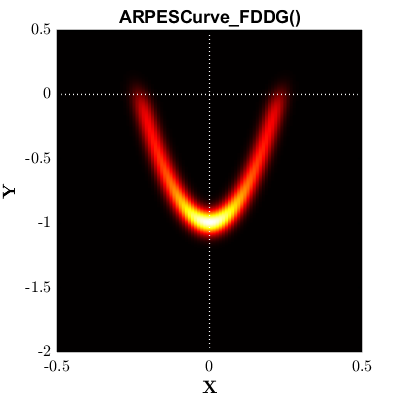

% 1 - Defining the input parameters
xdat = linspace(-0.5, 0.5, 1e2);    % 1xM row vector of the x-axis domain
ydat = linspace(-2, 0.5, 1e3)';        % Nx1 column vector of the y-axis domain
cTYPE   = "G2DA";       % type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
INT     = 1.0;          % scalar of the peak intensity of 2D PE curve.
XLOC    = 0.00;         % scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion.
YLOC    = -1.00;        % scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion.
XFWHM   = 0.05;         % scalar of the x-axis FWHM for each Gaussian (k-resolution)
YFWHM   = 0.15;         % scalar of the y-axis FWHM for each Gaussian (Eb-resolution)
MSTAR   = 0.20;         % scalar of the effective mass, which governs the curvature of the parabola.
FDEF    = 0.00;         % scalar of the FDD Fermi-Level position.
FDT     = 12.0;        % scalar of the FDD temperature.
FDW     = 0.20;        % scalar of the FDD Gaussian width after convolution.
% 2 - Calculating the lineshape
zdat    = ARPESCurve_FDDG(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR, FDEF, FDT, FDW, 1);

## (4) N Generic ARPES Curves with FDD Convolution + Gaussian broadening + linear background

help ARPESCurve_FDDGpL;

  zdat = ARPESCurve_FDDGpL(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR, FDEF, FDT, FDW, BGR, BIN, BCO, plot_result)
    Function that evaluates a generic angle-resolved photoelectron 
    spectroscopy (ARPES) curve in 2D. This can be used to model an ARPES
    spectrum, that is built up by a sum of individual Gaussians.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       [1×M] row vector of the x-axis input domain (kx for ARPES)
    -   ydat:       [N×1] column vector of the y-axis input domain (Eb for ARPES)
    -   cTYPE:      type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
    -   INT:    	scalar of the peak intensity of 2D PE curve.
    -   XLOC:      	scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion [Ang^-1].
    -   YLOC:      	scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion [eV].
    -   XFWHM:     	scalar of the x-axis FWHM for each Gaussian (k-resolution) [Ang^-1]
    - 

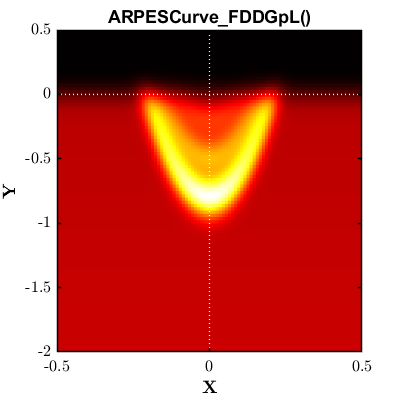

% 1 - Defining the input parameters
xdat = linspace(-0.5, 0.5, 1e2);      % 1xM row vector of the x-axis domain
ydat = linspace(-2, 0.5, 1e2)';       % Nx1 column vector of the y-axis domain
cTYPE   = ["G2DA"; "G2DA"; "G2DA"];   % type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
INT     = [1.0; 0.5; 0.25];           % scalar of the peak intensity of 2D PE curve.
XLOC    = [0.0; 0.0; 0.0];            % scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion.
YLOC    = [-0.8; -0.5; -0.2];         % scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion.
XFWHM   = [0.05; 0.05; 0.05];         % scalar of the x-axis FWHM for each Gaussian (k-resolution)
YFWHM   = [0.25; 0.25; 0.25];         % scalar of the y-axis FWHM for each Gaussian (Eb-resolution)
MSTAR   = [0.20; 0.20; 0.20];         % scalar of the effective mass, which governs the curvature of the parabola.
FDEF    =  0.00;        % scalar of the FDD Fermi-Level position.
FDT     =  12.0;        % scalar of the FDD temperature.
FDW     =  0.20;        % scalar of the FDD Gaussian width after convolution.
BGR     =  -0.1;        % scalar of the gradient of the linear background.
BIN     =  2;         % scalar of the y-intercept of the linear background.
BCO     =  0.10;        % scalar of the constant background y-offset value.
% 2 - Calculating the lineshape
zdat    = ARPESCurve_FDDGpL(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR, FDEF, FDT, FDW, BGR, BIN, BCO, 1);

## (5) Generic ARPES Curve with FDD Convolution + Gaussian broadening (Normalised)

help ARPESCurveNorm_FDDG;

  zdat = ARPESCurveNorm_FDDG(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR, FDEF, FDT, FDW, plot_result)
    Function that evaluates a generic angle-resolved photoelectron 
    spectroscopy (ARPES) curve in 2D. This can be used to model an ARPES
    spectrum, that is built up by a sum of individual Gaussians. The
    intensity is normalised across all EDCs.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       [1×M] row vector of the x-axis input domain (kx for ARPES)
    -   ydat:       [N×1] column vector of the y-axis input domain (Eb for ARPES)
    -   cTYPE:      type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
    -   INT:    	scalar of the peak intensity of 2D PE curve.
    -   XLOC:      	scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion [Ang^-1].
    -   YLOC:      	scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion [eV].
    -   XFWHM:     	scalar of the x-axis FWHM for each Gau

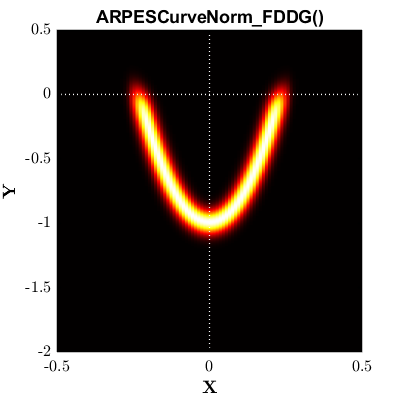

% 1 - Defining the input parameters
xdat = linspace(-0.5, 0.5, 1e2);    % 1xM row vector of the x-axis domain
ydat = linspace(-2, 0.5, 1e3)';        % Nx1 column vector of the y-axis domain
cTYPE   = "G2DA";       % type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
INT     = 1.0;          % scalar of the peak intensity of 2D PE curve.
XLOC    = 0.00;         % scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion.
YLOC    = -1.00;        % scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion.
XFWHM   = 0.05;         % scalar of the x-axis FWHM for each Gaussian (k-resolution)
YFWHM   = 0.15;         % scalar of the y-axis FWHM for each Gaussian (Eb-resolution)
MSTAR   = 0.20;         % scalar of the effective mass, which governs the curvature of the parabola.
FDEF    = 0.00;         % scalar of the FDD Fermi-Level position.
FDT     = 12.0;        % scalar of the FDD temperature.
FDW     = 0.20;        % scalar of the FDD Gaussian width after convolution.
% 2 - Calculating the lineshape
zdat    = ARPESCurveNorm_FDDG(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR, FDEF, FDT, FDW, 1);

# **APPENDIX : A LIST OF USEFUL MISCELLANEOUS ANALYSIS**

## **Appendix I -  Analysing the shift in the VBM / CBM position vs perpendicular angular acceptance window**

## (1) Simulating the InAs valence band

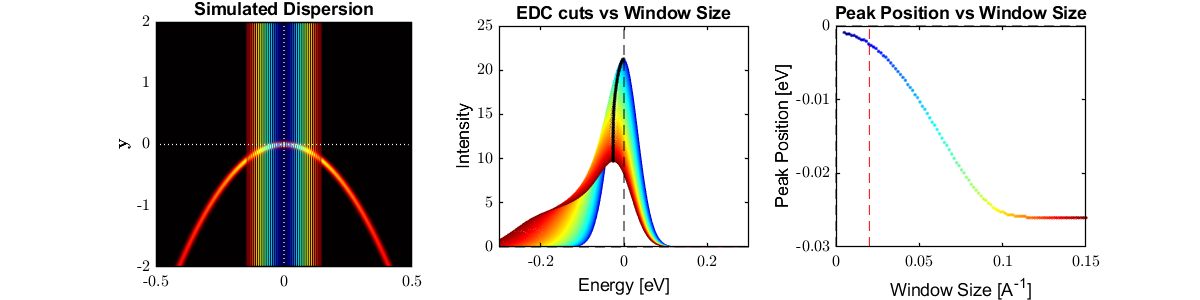

% 1 - Defining the input parameters
xdat = linspace(-0.5, 0.5, 1e3);    % 1xM row vector of the x-axis domain
ydat = linspace(-2, 2, 1e3)';        % Nx1 column vector of the y-axis domain
cTYPE   = "G2DA";       % type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
INT     = 1.0;          % scalar of the peak intensity of 2D PE curve.
XLOC    = 0.00;         % scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion.
YLOC    = 0.00;        % scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion.
XFWHM   = 0.02;         % scalar of the x-axis FWHM for each Gaussian (k-resolution)
YFWHM   = 0.08;         % scalar of the y-axis FWHM for each Gaussian (Eb-resolution)
MSTAR   = -0.32;         % scalar of the effective mass, which governs the curvature of the parabola.
% 2 - Extracting the ARPES dispersion
zdat    = ARPESCurve(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR);
% 3 - Defining the window size
WinVal = linspace(0.005, 0.15, 1e2);
xMode   = 'edc';
for i = 1:length(WinVal)
    Win                         = [-1, 1]*WinVal(i);
    [VB_XCut{i},VB_DCut{i}]     = Cut(xdat,ydat,zdat,xMode,Win);
    [VB_xVal{i}, VB_yVal{i}] = find_peak_loc(VB_XCut{i},VB_DCut{i}, [-0.1, 0.1], "spline", 0);
end
% 4 - Final plot summary
fig = figure(); 
fig.Position(3) = 3.00*pp.fig4x4(1); 
fig.Position(4) = 0.75*pp.fig4x4(2);
col = jet(length(WinVal));
% Plotting the ARPES bands
subplot(131); hold on;
ImData(xdat, ydat, zdat);
% Plotting the window size cuts
for i = 1:5:length(WinVal)
    line([1, 1]*WinVal(i), [-1e5, 1e5], 'Color', col(i,:), 'LineWidth', 0.25, 'Linestyle', '-');
    line([1, 1]*-WinVal(i), [-1e5, 1e5], 'Color', col(i,:), 'LineWidth', 0.25, 'Linestyle', '-');
end
img_props(); 
xlabel('$$ \bf  x $$', 'Interpreter', 'latex');
ylabel('$$ \bf  y $$', 'Interpreter', 'latex');
title('Simulated Dispersion', 'Interpreter', 'none');
axis([min(xdat(:)), max(xdat(:)), min(ydat(:)), max(ydat(:))]);
% Plotting the analysis
for i = 1:length(WinVal)
    subplot(132); hold on; plot(VB_XCut{i}, VB_DCut{i}, 'color', col(i,:));
    plot(VB_xVal{i}, VB_yVal{i}, 'k.');
    subplot(133); hold on; plot(WinVal(i), VB_xVal{i}, 'k.', 'color', col(i,:));
end
% Formatting the axes
subplot(132); 
gca_props();
xlim([-0.3, 0.3]);
xlabel('Energy [eV]');
ylabel('Intensity');
title('EDC cuts vs Window Size', 'Interpreter', 'none');
subplot(133); 
gca_props();
ylim([-0.03, 0]);
xlabel('Window Size [A^{-1}]');
ylabel('Peak Position [eV]');
title('Peak Position vs Window Size', 'Interpreter', 'none');
line([0.02 0.02], [-1e5, 1e5], 'Color', [1 0 0], 'LineWidth', 0.75, 'Linestyle', '--');

## (2) Simulating the InAs conduction band

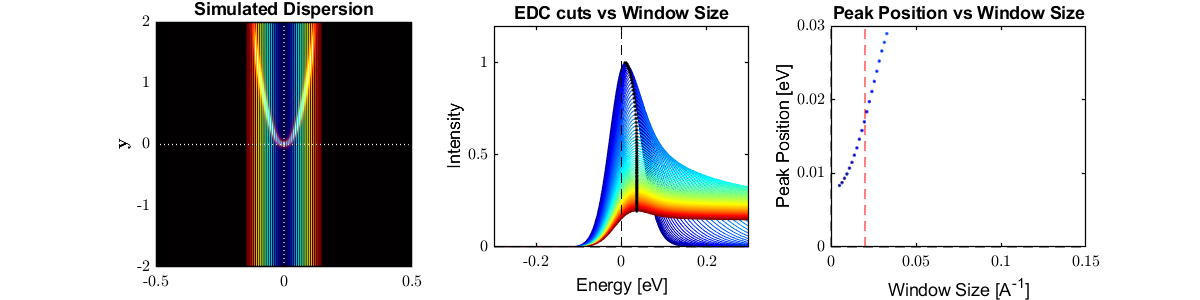

% 1 - Defining the input parameters
xdat = linspace(-0.5, 0.5, 1e3);    % 1xM row vector of the x-axis domain
ydat = linspace(-2, 2, 1e3)';        % Nx1 column vector of the y-axis domain
cTYPE   = "G2DA";       % type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
INT     = 1.0;          % scalar of the peak intensity of 2D PE curve.
XLOC    = 0.00;         % scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion.
YLOC    = 0.00;        % scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion.
XFWHM   = 0.02;         % scalar of the x-axis FWHM for each Gaussian (k-resolution)
YFWHM   = 0.08;         % scalar of the y-axis FWHM for each Gaussian (Eb-resolution)
MSTAR   = 0.03;         % scalar of the effective mass, which governs the curvature of the parabola.
% 2 - Extracting the ARPES dispersion
zdat    = ARPESCurveNorm(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR);
% 3 - Defining the window size
WinVal = linspace(0.005, 0.15, 1e2);
xMode   = 'edc';
for i = 1:length(WinVal)
    Win                         = [-1, 1]*WinVal(i);
    [CB_XCut{i},CB_DCut{i}]     = Cut(xdat,ydat,zdat,xMode,Win);
    [CB_xVal{i}, CB_yVal{i}] = find_peak_loc(CB_XCut{i},CB_DCut{i}, [-0.1, 0.1], "spline", 0);
end
% 4 - Final plot summary
fig = figure(); 
fig.Position(3) = 3.00*pp.fig4x4(1); 
fig.Position(4) = 0.75*pp.fig4x4(2);
col = jet(length(WinVal));
% Plotting the ARPES bands
subplot(131); hold on;
ImData(xdat, ydat, zdat);
% Plotting the window size cuts
for i = 1:5:length(WinVal)
    line([1, 1]*WinVal(i), [-1e5, 1e5], 'Color', col(i,:), 'LineWidth', 0.25, 'Linestyle', '-');
    line([1, 1]*-WinVal(i), [-1e5, 1e5], 'Color', col(i,:), 'LineWidth', 0.25, 'Linestyle', '-');
end
img_props(); 
xlabel('$$ \bf  x $$', 'Interpreter', 'latex');
ylabel('$$ \bf  y $$', 'Interpreter', 'latex');
title('Simulated Dispersion', 'Interpreter', 'none');
axis([min(xdat(:)), max(xdat(:)), min(ydat(:)), max(ydat(:))]);
% Plotting the analysis
for i = 1:length(WinVal)
    subplot(132); hold on; plot(CB_XCut{i}, CB_DCut{i}, 'color', col(i,:));
    plot(CB_xVal{i}, CB_yVal{i}, 'k.');
    subplot(133); hold on; plot(WinVal(i), CB_xVal{i}, 'k.', 'color', col(i,:));
end
% Formatting the axes
subplot(132); 
gca_props();
xlim([-0.3, 0.3]);
xlabel('Energy [eV]');
ylabel('Intensity');
title('EDC cuts vs Window Size', 'Interpreter', 'none');
subplot(133); 
gca_props();
ylim([0, 0.03]);
xlabel('Window Size [A^{-1}]');
ylabel('Peak Position [eV]');
title('Peak Position vs Window Size', 'Interpreter', 'none');
line([0.02 0.02], [-1e5, 1e5], 'Color', [1 0 0], 'LineWidth', 0.75, 'Linestyle', '--');

## (3) Simulating gated experiments

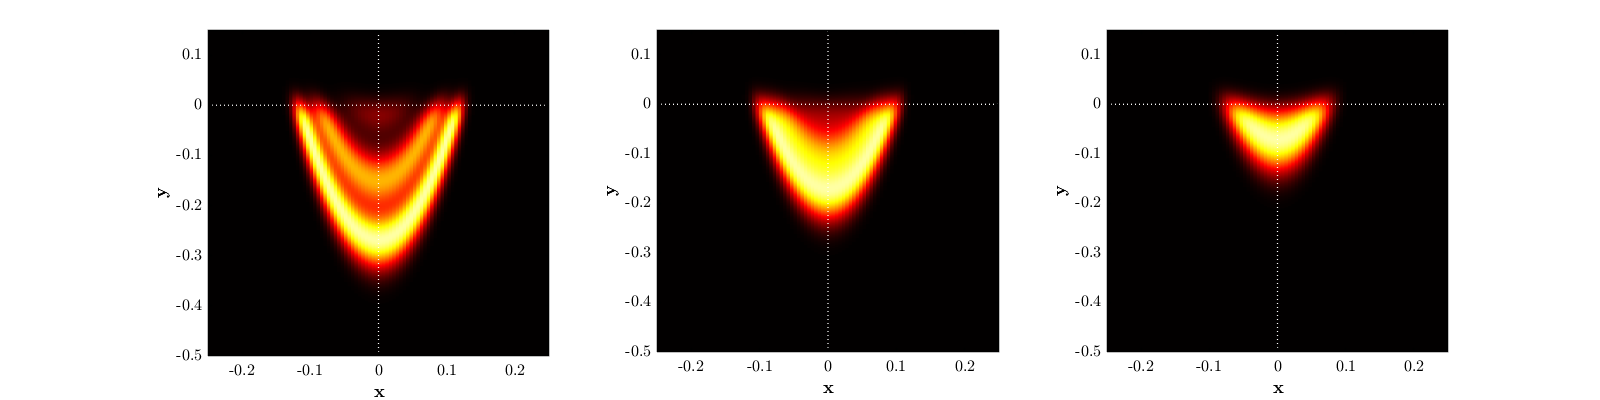

% 1 - Defining the input parameters
xdat = linspace(-0.25, 0.25, 1e2);    % 1xM row vector of the x-axis domain
ydat = linspace(-0.5, 0.15, 1e3)';        % Nx1 column vector of the y-axis domain
cTYPE   = ["G2DA"; "G2DA"; "G2DA"];   % type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
INT     = [1.0; 0.7; 0.3];           % scalar of the peak intensity of 2D PE curve.
XLOC    = [0.0; 0.0; 0.0];            % scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion.
YLOC    = [-0.18; -0.10; -0.00];         % scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion.
XFWHM   = 0.01*[1;1;1];         % scalar of the x-axis FWHM for each Gaussian (k-resolution)
YFWHM   = 0.09*[1;1;1];         % scalar of the y-axis FWHM for each Gaussian (Eb-resolution)
MSTAR   = 0.19*[1;1;1];         % scalar of the effective mass, which governs the curvature of the parabola.
FDEF    = 0.00;         % scalar of the FDD Fermi-Level position.
FDT     = 12.0;        % scalar of the FDD temperature.
FDW     = 0.05;        % scalar of the FDD Gaussian width after convolution.
% 2 - Calculating the lineshape
zdat_01    = ARPESCurveNorm_FDDG(xdat, ydat, cTYPE, INT, XLOC, 1.5*YLOC, XFWHM, YFWHM, MSTAR, FDEF, FDT, FDW);
zdat_02    = ARPESCurveNorm_FDDG(xdat, ydat, cTYPE, INT, XLOC, 1.0*YLOC, XFWHM, YFWHM, MSTAR, FDEF, FDT, FDW);
zdat_03    = ARPESCurveNorm_FDDG(xdat, ydat, cTYPE, INT, XLOC, 0.5*YLOC, XFWHM, YFWHM, MSTAR, FDEF, FDT, FDW);
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); fig.Position(3) = 4.*pp.fig4x4(1); fig.Position(4) = pp.fig4x4(2);
subplot(131); hold on;
ImData(xdat, ydat, zdat_01); img_props();
xlabel('$$ \bf  x $$', 'Interpreter', 'latex');
ylabel('$$ \bf  y $$', 'Interpreter', 'latex');
axis([min(xdat(:)), max(xdat(:)), min(ydat(:)), max(ydat(:))]);
caxis([0, 1.1]);
subplot(132); hold on;
ImData(xdat, ydat, zdat_02); img_props();
xlabel('$$ \bf  x $$', 'Interpreter', 'latex');
ylabel('$$ \bf  y $$', 'Interpreter', 'latex');
axis([min(xdat(:)), max(xdat(:)), min(ydat(:)), max(ydat(:))]);
caxis([0, 1.1]);
subplot(133); hold on;
ImData(xdat, ydat, zdat_03); img_props();
xlabel('$$ \bf  x $$', 'Interpreter', 'latex');
ylabel('$$ \bf  y $$', 'Interpreter', 'latex');
axis([min(xdat(:)), max(xdat(:)), min(ydat(:)), max(ydat(:))]);
caxis([0, 1.1]);